# EE536 HW 7

Qingchuan Hou

Dec 7 2022

clc

syms T_em T_shaft T_d theta_l omega_l theta_m omega_m theta_l_ast omega_l_ast theta_m_ast omega_m_ast s
syms K_lisa K_lsa b_la b_ra K_misa K_msa b_ma 
syms J_m J_l b_r K_r

% Physical System Resonant Load
eq1 = theta_l == omega_l/s

$$eq1 = \theta_{l}=\frac{\omega_{l}}{s}$$

eq2 = omega_l == (1/(J_l*s)) * (T_shaft - T_d)

$$eq2 = \omega_{l}=-\frac{T_{d}-T_{\mathrm{shaft}}}{J_{l}\,s}$$

eq3 = T_shaft == (theta_m-theta_l) * K_r + (omega_m-omega_l) * b_r

$$eq3 = T_{\mathrm{shaft}}=-K_{r}\,\left(\theta_{l}-\theta_{m}\right)-b_{r}\,\left(\omega_{l}-\omega_{m}\right)$$

eq4 = theta_m == omega_m/s

$$eq4 = \theta_{m}=\frac{\omega_{m}}{s}$$

eq5 = omega_m == (1/(J_m*s)) * (T_em + (theta_l-theta_m) * K_r + (omega_l-omega_m) * b_r)

$$eq5 = \omega_{m}=\frac{T_{\mathrm{em}}+K_{r}\,\left(\theta_{l}-\theta_{m}\right)+b_{r}\,\left(\omega_{l}-\omega_{m}\right)}{J_{m}\,s}$$


J_m = 6e-3;  J_l = 2e-3;  b_r = 5e-3;  K_r = 5e+2;
syms tau_1 tau_2

## LA

% Virtual Reference for LA
eq6_1 = T_em == (theta_l_ast-theta_l) * (K_lisa/s + K_lsa) + (omega_l_ast - omega_l)*b_la 

$$eq6\_1 = T_{\mathrm{em}}=-\left(K_{\mathrm{lsa}}+\frac{K_{\mathrm{lisa}}}{s}\right)\,\left(\theta_{l}-\theta_{l^{*}}\right)-b_{\mathrm{la}}\,\left(\omega_{l}-\omega_{l^{*}}\right)$$

eq7_1 = theta_l_ast == omega_l_ast/s

$$eq7\_1 = \theta_{l^{*}}=\frac{\omega_{l^{*}}}{s}$$


eqs_1 = [eq1,eq2,eq3,eq4,eq5,eq6_1,eq7_1];

S1_1 = solve(eqs_1, [theta_l, T_em, T_shaft, omega_l, omega_l_ast, omega_m, theta_m]);

EQ_1 = theta_l == collect(S1_1.theta_l, [theta_l_ast, T_d])

$$EQ\_1 = \begin{array}{l} \theta_{l}=\frac{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3}}{\sigma_{1}}\,\theta_{l^{*}}+\left(-\frac{J_{m}\,s^{3}+b_{r}\,s^{2}+K_{r}\,s}{\sigma_{1}}\right)\,T_{d}\\ \mathrm{where}\\ \sigma_{1}=K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{r}\,s^{4}+J_{m}\,b_{r}\,s^{4}+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3} \end{array}$$


subtheta_1 = children(rhs(EQ_1));
% Trasfer function for theta
TF_theta_1 = theta_l/theta_l_ast == subtheta_1(1)/theta_l_ast

$$TF\_theta\_1 = \begin{array}{l} \frac{\theta_{l}}{\theta_{l^{*}}}=\frac{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+\sigma_{3}+\sigma_{2}+\sigma_{1}}{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{r}\,s^{4}+J_{m}\,b_{r}\,s^{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=b_{\mathrm{la}}\,b_{r}\,s^{3}\\ \sigma_{2}=K_{\mathrm{lsa}}\,b_{r}\,s^{2}\\ \sigma_{3}=K_{r}\,b_{\mathrm{la}}\,s^{2} \end{array}$$


[n_theta_1, d_theta_1] = numden(rhs(TF_theta_1));
% character equation for poles
eq8_1 = collect(d_theta_1,s) == 0

$$eq8\_1 = \left(J_{l}\,J_{m}\right)\,s^{5}+\left(J_{l}\,b_{r}+J_{m}\,b_{r}\right)\,s^{4}+\left(b_{\mathrm{la}}\,b_{r}+J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\left(K_{r}\,b_{\mathrm{la}}+K_{\mathrm{lsa}}\,b_{r}\right)\,s^{2}+\left(K_{\mathrm{lisa}}\,b_{r}+K_{\mathrm{lsa}}\,K_{r}\right)\,s+K_{\mathrm{lisa}}\,K_{r}=0$$


% fill in paramters
EQ1_1 = collect(subs(lhs(eq8_1)),s) == 0

$$EQ1\_1 = \frac{3\,s^{5}}{250000}+\frac{s^{4}}{25000}+\left(\frac{b_{\mathrm{la}}}{200}+4\right)\,s^{3}+\left(\frac{K_{\mathrm{lsa}}}{200}+500\,b_{\mathrm{la}}\right)\,s^{2}+\left(500\,K_{\mathrm{lsa}}+\frac{K_{\mathrm{lisa}}}{200}\right)\,s+500\,K_{\mathrm{lisa}}=0$$


% poles at 1,10,100Hz
eq10_1 = (s + 2*pi) * (s + 2*pi*10) * (s + 2*pi*100) * (s + tau_1) * (s + tau_2) == 0

$$eq10\_1 = \left(s+\tau_{1}\right)\,\left(s+\tau_{2}\right)\,\left(s+2\,\pi \right)\,\left(s+20\,\pi \right)\,\left(s+200\,\pi \right)=0$$

EQ2_1 = collect(eq10_1,s)

$$EQ2\_1 = \begin{array}{l} s^{5}+\left(\tau_{1}+\tau_{2}+222\,\pi \right)\,s^{4}+\left(\tau_{1}\,\tau_{2}+\sigma_{1}+200\,\pi \,\left(\tau_{1}+\tau_{2}+22\,\pi \right)+\sigma_{3}\right)\,s^{3}+\left(\sigma_{2}+200\,\pi \,\left(\tau_{1}\,\tau_{2}+\sigma_{1}+\sigma_{3}\right)+2\,\pi \,\tau_{1}\,\tau_{2}\right)\,s^{2}+\left(200\,\pi \,\left(\sigma_{2}+2\,\pi \,\tau_{1}\,\tau_{2}\right)+40\,\tau_{1}\,\tau_{2}\,\pi^{2}\right)\,s+8000\,\tau_{1}\,\tau_{2}\,\pi^{3}=0\\ \mathrm{where}\\ \sigma_{1}=20\,\pi \,\left(\tau_{1}+\tau_{2}+2\,\pi \right)\\ \sigma_{2}=20\,\pi \,\left(\tau_{1}\,\tau_{2}+\sigma_{3}\right)\\ \sigma_{3}=2\,\pi \,\left(\tau_{1}+\tau_{2}\right) \end{array}$$


subpoles1_1 = children(lhs(EQ1_1));
subpoles2_1 = children(lhs(EQ2_1));

% solve polos
eq11_1 = (subpoles1_1{2}/s^4) / (subpoles1_1{1}/s^5) == subpoles2_1{2}/s^4

$$eq11\_1 = \frac{10}{3}=\tau_{1}+\tau_{2}+222\,\pi$$

eq12_1 = (subpoles1_1{3}/s^3) / (subpoles1_1{1}/s^5) == subpoles2_1{3}/s^3

$$eq12\_1 = \frac{1250\,b_{\mathrm{la}}}{3}+\frac{1000000}{3}=\tau_{1}\,\tau_{2}+20\,\pi \,\left(\tau_{1}+\tau_{2}+2\,\pi \right)+200\,\pi \,\left(\tau_{1}+\tau_{2}+22\,\pi \right)+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)$$

eq13_1 = (subpoles1_1{4}/s^2) / (subpoles1_1{1}/s^5) == subpoles2_1{4}/s^2

$$eq13\_1 = \frac{1250\,K_{\mathrm{lsa}}}{3}+\frac{125000000\,b_{\mathrm{la}}}{3}=20\,\pi \,\left(\tau_{1}\,\tau_{2}+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)\right)+200\,\pi \,\left(\tau_{1}\,\tau_{2}+20\,\pi \,\left(\tau_{1}+\tau_{2}+2\,\pi \right)+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)\right)+2\,\pi \,\tau_{1}\,\tau_{2}$$

eq14_1 = (subpoles1_1{5}/s) / (subpoles1_1{1}/s^5) == subpoles2_1{5}/s

$$eq14\_1 = \frac{125000000\,K_{\mathrm{lsa}}}{3}+\frac{1250\,K_{\mathrm{lisa}}}{3}=200\,\pi \,\left(20\,\pi \,\left(\tau_{1}\,\tau_{2}+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)\right)+2\,\pi \,\tau_{1}\,\tau_{2}\right)+40\,\tau_{1}\,\tau_{2}\,\pi^{2}$$

eq15_1 = subpoles1_1{6}/ (subpoles1_1{1}/s^5) == subpoles2_1{6}

$$eq15\_1 = \frac{125000000\,K_{\mathrm{lisa}}}{3}=8000\,\tau_{1}\,\tau_{2}\,\pi^{3}$$


[K_lisa_s1,K_lsa_s1,b_la_s1,tau_1_s1,tau_2_s1] = solve([eq11_1,eq12_1,eq13_1,eq14_1,eq15_1],[K_lisa,K_lsa,b_la,tau_1,tau_2])

$$K\_lisa\_s1 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{64\,\pi^{3}\,\left(84082777500\,\pi^{2}-1387500000\,\pi -18331505\,\pi^{3}+333\,\pi^{4}+625000000000\right)}{5\,\left(277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\right)} \end{array}$$

$$K\_lsa\_s1 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{24\,\left(23125000000000\,\pi^{2}-51337500000\,\pi^{3}+3083312767500\,\pi^{4}-672715685\,\pi^{5}+12221\,\pi^{6}\right)}{125\,\left(277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\right)} \end{array}$$

$$b\_la\_s1 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{6\,\left(23125000000000\,\pi -51337500000\,\pi^{2}+2805537767500\,\pi^{3}-616660685\,\pi^{4}+11211\,\pi^{5}\right)}{625\,\left(277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\right)} \end{array}$$

$$tau\_1\_s1 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-111\,\pi +\frac{5}{3}\\ \frac{5}{3}-\sigma_{1}-111\,\pi \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\frac{4\,\left(36587617423612500\,\pi^{2}-416243062500000\,\pi +19772979315025\,\pi^{3}-5954542830\,\pi^{4}+110889\,\pi^{5}+374996875000000000\right)}{9\,\left(\pi -500\right)\,\left(\pi -5000\right)\,\left(\pi -50000\right)}}}{2} \end{array}$$

$$tau\_2\_s1 = \begin{array}{l} \left(\begin{array}{c} \frac{5}{3}-\sigma_{1}-111\,\pi \\ \sigma_{1}-111\,\pi +\frac{5}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{\frac{4\,\left(36587617423612500\,\pi^{2}-416243062500000\,\pi +19772979315025\,\pi^{3}-5954542830\,\pi^{4}+110889\,\pi^{5}+374996875000000000\right)}{9\,\left(\pi -500\right)\,\left(\pi -5000\right)\,\left(\pi -50000\right)}}}{2} \end{array}$$

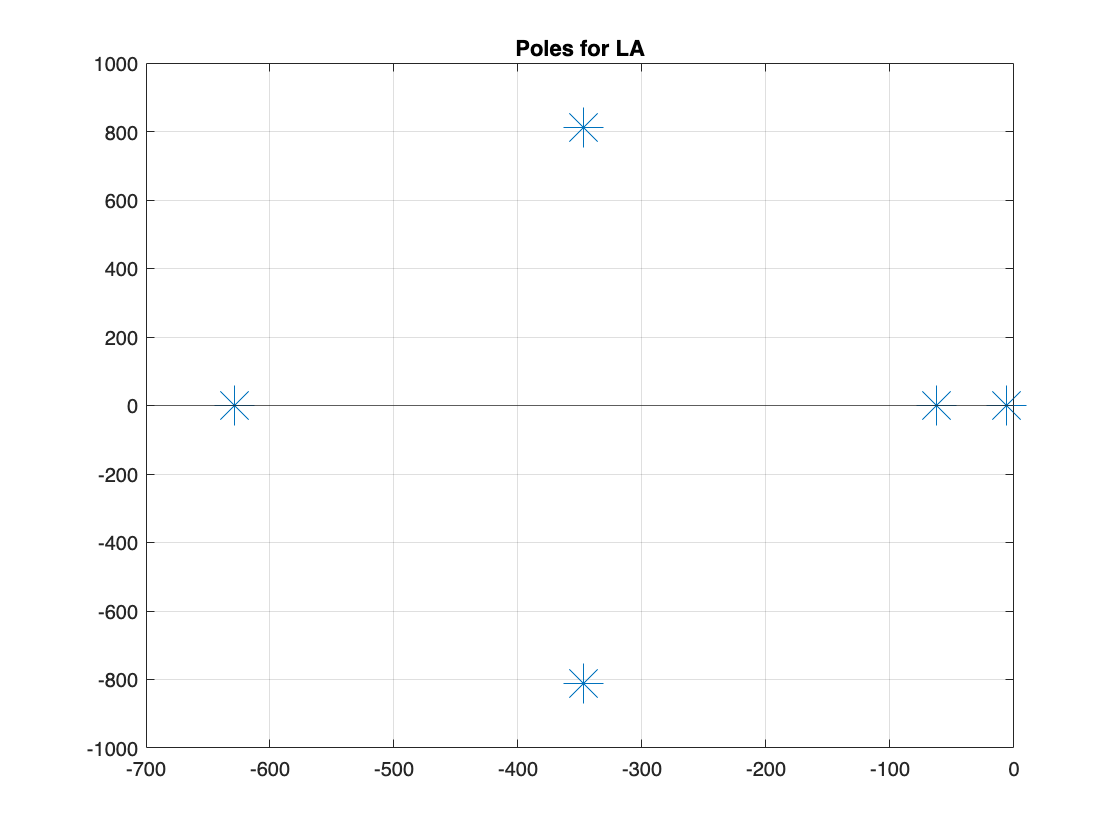


% pols plots
taus_1 = [-2*pi, -2*pi*10, -2*pi*100, tau_1_s1(1), tau_2_s1(1)];
plot(real(taus_1), imag(taus_1), '*', 'MarkerSize', 20)
grid on
xline(0);
yline(0);
title('Poles for LA')

% Dynamic stiffness
DS1_1 = T_d/theta_l == 1/(subtheta_1(2)/T_d)

$$DS1\_1 = \frac{T_{d}}{\theta_{l}}=-\frac{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{r}\,s^{4}+J_{m}\,b_{r}\,s^{4}+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3}}{J_{m}\,s^{3}+b_{r}\,s^{2}+K_{r}\,s}$$

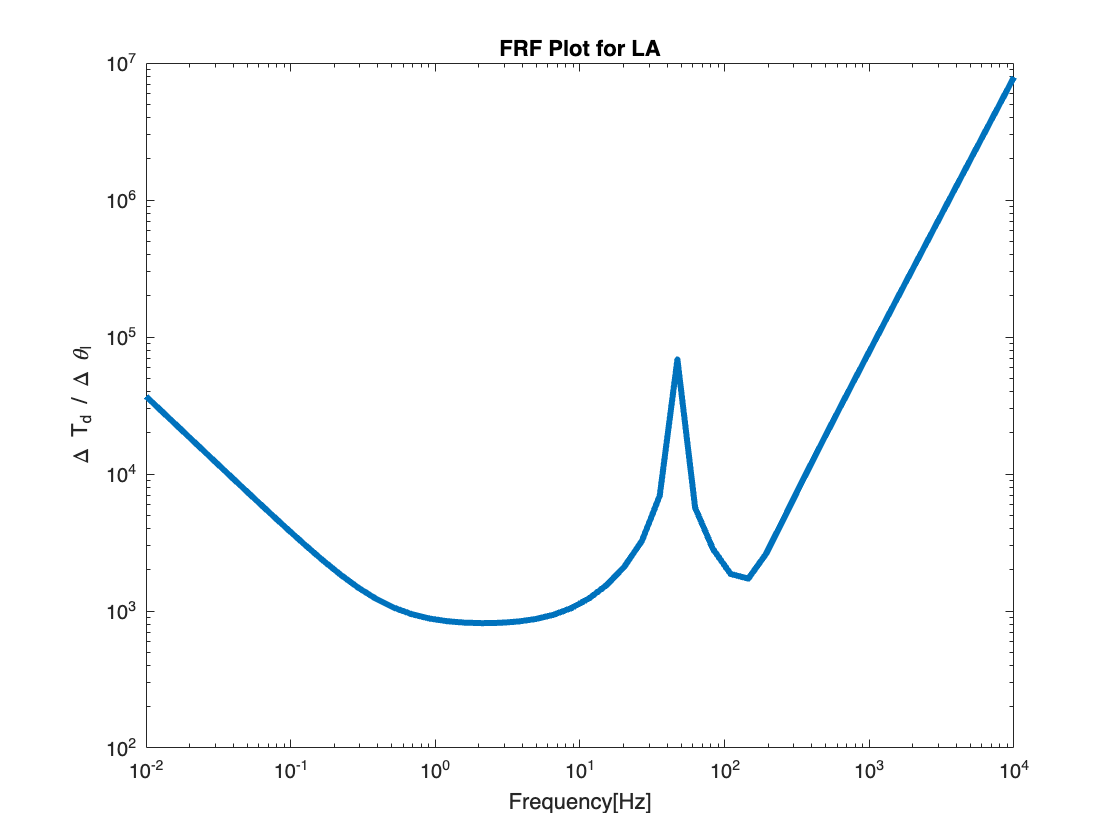

DS2_1 = subs(DS1_1);
DS3_1 = subs(DS2_1,[K_lisa,K_lsa,b_la],[K_lisa_s1(1)/sort(2),K_lsa_s1(1),b_la_s1(1)]);

fr = logspace(-2,4);
DS4_1 = subs(DS3_1,s,2*pi*fr*1j);

loglog(fr, abs(rhs(DS4_1)), 'LineWidth', 3)
xlabel('Frequency[Hz]') 
ylabel('\Delta T_d / \Delta \theta_l') 
title('FRF Plot for LA')

## LARA

% Virtual Reference for LARA
eq6_2 = T_em == (theta_l_ast-theta_l) * (K_lisa/s + K_lsa) + (omega_l_ast - omega_l)*b_la + (omega_l-omega_m)*b_ra

$$eq6\_2 = T_{\mathrm{em}}=b_{\mathrm{ra}}\,\left(\omega_{l}-\omega_{m}\right)-b_{\mathrm{la}}\,\left(\omega_{l}-\omega_{l^{*}}\right)-\left(K_{\mathrm{lsa}}+\frac{K_{\mathrm{lisa}}}{s}\right)\,\left(\theta_{l}-\theta_{l^{*}}\right)$$

eq7_2 = theta_l_ast == omega_l_ast/s

$$eq7\_2 = \theta_{l^{*}}=\frac{\omega_{l^{*}}}{s}$$


eqs_2 = [eq1,eq2,eq3,eq4,eq5,eq6_2,eq7_2];

S1_2 = solve(eqs_2, [theta_l, T_em, T_shaft, omega_l, omega_l_ast, omega_m, theta_m]);

EQ_2 = theta_l == collect(S1_2.theta_l, [theta_l_ast, T_d])

$$EQ\_2 = \begin{array}{l} \theta_{l}=\frac{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3}}{\sigma_{1}}\,\theta_{l^{*}}+\left(-\frac{K_{r}\,s+J_{m}\,s^{3}+b_{r}\,s^{2}+b_{\mathrm{ra}}\,s^{2}}{\sigma_{1}}\right)\,T_{d}\\ \mathrm{where}\\ \sigma_{1}=K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{r}\,s^{4}+J_{l}\,b_{\mathrm{ra}}\,s^{4}+J_{m}\,b_{r}\,s^{4}+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3} \end{array}$$


subtheta_2 = children(rhs(EQ_2));
% Trasfer function for theta
TF_theta_2 = theta_l/theta_l_ast == subtheta_2(1)/theta_l_ast

$$TF\_theta\_2 = \begin{array}{l} \frac{\theta_{l}}{\theta_{l^{*}}}=\frac{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+\sigma_{3}+\sigma_{2}+\sigma_{1}}{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{r}\,s^{4}+J_{l}\,b_{\mathrm{ra}}\,s^{4}+J_{m}\,b_{r}\,s^{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=b_{\mathrm{la}}\,b_{r}\,s^{3}\\ \sigma_{2}=K_{\mathrm{lsa}}\,b_{r}\,s^{2}\\ \sigma_{3}=K_{r}\,b_{\mathrm{la}}\,s^{2} \end{array}$$


[n_theta_2, d_theta_2] = numden(rhs(TF_theta_2));
% character equation for poles
eq8_2 = collect(d_theta_2,s) == 0

$$eq8\_2 = \left(J_{l}\,J_{m}\right)\,s^{5}+\left(J_{l}\,b_{r}+J_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{4}+\left(b_{\mathrm{la}}\,b_{r}+J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\left(K_{r}\,b_{\mathrm{la}}+K_{\mathrm{lsa}}\,b_{r}\right)\,s^{2}+\left(K_{\mathrm{lisa}}\,b_{r}+K_{\mathrm{lsa}}\,K_{r}\right)\,s+K_{\mathrm{lisa}}\,K_{r}=0$$


% fill in paramters
EQ1_2 = collect(subs(lhs(eq8_2)),s) == 0

$$EQ1\_2 = \frac{3\,s^{5}}{250000}+\left(\frac{b_{\mathrm{ra}}}{500}+\frac{1}{25000}\right)\,s^{4}+\left(\frac{b_{\mathrm{la}}}{200}+4\right)\,s^{3}+\left(\frac{K_{\mathrm{lsa}}}{200}+500\,b_{\mathrm{la}}\right)\,s^{2}+\left(500\,K_{\mathrm{lsa}}+\frac{K_{\mathrm{lisa}}}{200}\right)\,s+500\,K_{\mathrm{lisa}}=0$$


% poles at 1,10,100Hz
eq10_2 = (s + 2*pi) * (s + 2*pi*10) * (s + 2*pi*100) * (s + tau_1) * (s + tau_1) == 0

$$eq10\_2 = {\left(s+\tau_{1}\right)}^{2}\,\left(s+2\,\pi \right)\,\left(s+20\,\pi \right)\,\left(s+200\,\pi \right)=0$$

EQ2_2 = collect(eq10_2,s)

$$EQ2\_2 = \begin{array}{l} s^{5}+\left(2\,\tau_{1}+222\,\pi \right)\,s^{4}+\left(4\,\pi \,\tau_{1}+\sigma_{2}+200\,\pi \,\left(2\,\tau_{1}+22\,\pi \right)+{\tau_{1}}^{2}\right)\,s^{3}+\left(\sigma_{1}+\sigma_{3}+200\,\pi \,\left(4\,\pi \,\tau_{1}+\sigma_{2}+{\tau_{1}}^{2}\right)\right)\,s^{2}+\left(\pi \,\left(\sigma_{1}+\sigma_{3}\right)\,200+40\,{\tau_{1}}^{2}\,\pi^{2}\right)\,s+8000\,{\tau_{1}}^{2}\,\pi^{3}=0\\ \mathrm{where}\\ \sigma_{1}=\pi \,\left({\tau_{1}}^{2}+4\,\pi \,\tau_{1}\right)\,20\\ \sigma_{2}=20\,\pi \,\left(2\,\tau_{1}+2\,\pi \right)\\ \sigma_{3}=2\,\pi \,{\tau_{1}}^{2} \end{array}$$


subpoles1_2 = children(lhs(EQ1_2));
subpoles2_2 = children(lhs(EQ2_2));

% solve polos
eq11_2 = (subpoles1_2{2}/s^4) / (subpoles1_2{1}/s^5) == subpoles2_2{2}/s^4

$$eq11\_2 = \frac{500\,b_{\mathrm{ra}}}{3}+\frac{10}{3}=2\,\tau_{1}+222\,\pi$$

eq12_2 = (subpoles1_2{3}/s^3) / (subpoles1_2{1}/s^5) == subpoles2_2{3}/s^3

$$eq12\_2 = \frac{1250\,b_{\mathrm{la}}}{3}+\frac{1000000}{3}=4\,\pi \,\tau_{1}+20\,\pi \,\left(2\,\tau_{1}+2\,\pi \right)+200\,\pi \,\left(2\,\tau_{1}+22\,\pi \right)+{\tau_{1}}^{2}$$

eq13_2 = (subpoles1_2{4}/s^2) / (subpoles1_2{1}/s^5) == subpoles2_2{4}/s^2

$$eq13\_2 = \frac{1250\,K_{\mathrm{lsa}}}{3}+\frac{125000000\,b_{\mathrm{la}}}{3}=\pi \,\left({\tau_{1}}^{2}+4\,\pi \,\tau_{1}\right)\,20+2\,\pi \,{\tau_{1}}^{2}+200\,\pi \,\left(4\,\pi \,\tau_{1}+20\,\pi \,\left(2\,\tau_{1}+2\,\pi \right)+{\tau_{1}}^{2}\right)$$

eq14_2 = (subpoles1_2{5}/s) / (subpoles1_2{1}/s^5) == subpoles2_2{5}/s

$$eq14\_2 = \frac{125000000\,K_{\mathrm{lsa}}}{3}+\frac{1250\,K_{\mathrm{lisa}}}{3}=\pi \,\left(\pi \,\left({\tau_{1}}^{2}+4\,\pi \,\tau_{1}\right)\,20+2\,\pi \,{\tau_{1}}^{2}\right)\,200+40\,{\tau_{1}}^{2}\,\pi^{2}$$

eq15_2 = subpoles1_2{6}/ (subpoles1_2{1}/s^5) == subpoles2_2{6}

$$eq15\_2 = \frac{125000000\,K_{\mathrm{lisa}}}{3}=8000\,{\tau_{1}}^{2}\,\pi^{3}$$


[K_lisa_s2,K_lsa_s2,b_la_s2,b_ra_s2,tau_1_s2] = solve([eq11_2,eq12_2,eq13_2,eq14_2,eq15_2],[K_lisa,K_lsa,b_la,b_ra,tau_1])

$$K\_lisa\_s2 = \begin{array}{l} \left(\begin{array}{c} -\frac{40000000000000\,\pi^{3}-532800000000\,\pi^{5}+9600000\,\pi^{6}-\frac{26640000000\,\pi^{4}\,\sigma_{4}}{\sigma_{1}}+\frac{5328000\,\pi^{5}\,\sigma_{4}}{\sigma_{1}}-\frac{96\,\pi^{6}\,\sigma_{4}}{\sigma_{1}}}{\sigma_{2}}\\ -\frac{40000000000000\,\pi^{3}-532800000000\,\pi^{5}+9600000\,\pi^{6}-\frac{26640000000\,\pi^{4}\,\sigma_{3}}{\sigma_{1}}+\frac{5328000\,\pi^{5}\,\sigma_{3}}{\sigma_{1}}-\frac{96\,\pi^{6}\,\sigma_{3}}{\sigma_{1}}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\\ \sigma_{2}=1387500000\,\pi -277500\,\pi^{2}+5\,\pi^{3}-625000000000\\ \sigma_{3}=55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}-\sigma_{5}\\ \sigma_{4}=55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}+\sigma_{5}\\ \sigma_{5}=\sqrt{2802759250000000000000000000\,\pi^{2}-46250000000000000000000000\,\pi -\frac{1833150500000000000000000\,\pi^{3}}{3}+11100000000000000000\,\pi^{4}+\frac{62500000000000000000000000000}{3}} \end{array}$$

$$K\_lsa\_s2 = \begin{array}{l} \left(\begin{array}{c} \frac{10000000000\,\pi^{3}-555000000000000\,\pi^{2}+7392600000000\,\pi^{4}-266400000\,\pi^{5}+2400\,\pi^{6}+\frac{366630000000\,\pi^{3}\,\sigma_{4}}{\sigma_{1}}-\frac{73926000\,\pi^{4}\,\sigma_{4}}{\sigma_{1}}+\frac{1332\,\pi^{5}\,\sigma_{4}}{\sigma_{1}}}{\sigma_{2}}\\ \frac{10000000000\,\pi^{3}-555000000000000\,\pi^{2}+7392600000000\,\pi^{4}-266400000\,\pi^{5}+2400\,\pi^{6}+\frac{366630000000\,\pi^{3}\,\sigma_{3}}{\sigma_{1}}-\frac{73926000\,\pi^{4}\,\sigma_{3}}{\sigma_{1}}+\frac{1332\,\pi^{5}\,\sigma_{3}}{\sigma_{1}}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\\ \sigma_{2}=34687500000\,\pi -6937500\,\pi^{2}+125\,\pi^{3}-15625000000000\\ \sigma_{3}=55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}-\sigma_{5}\\ \sigma_{4}=55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}+\sigma_{5}\\ \sigma_{5}=\sqrt{2802759250000000000000000000\,\pi^{2}-46250000000000000000000000\,\pi -\frac{1833150500000000000000000\,\pi^{3}}{3}+11100000000000000000\,\pi^{4}+\frac{62500000000000000000000000000}{3}} \end{array}$$

$$b\_la\_s2 = \begin{array}{l} \left(\begin{array}{c} \frac{27750000000\,\pi^{2}-138750000000000\,\pi +1833149500000\,\pi^{3}-369630000\,\pi^{4}+6660\,\pi^{5}+\frac{84082500000\,\pi^{2}\,\sigma_{4}}{\sigma_{1}}-\frac{18331500\,\pi^{3}\,\sigma_{4}}{\sigma_{1}}+\frac{333\,\pi^{4}\,\sigma_{4}}{\sigma_{1}}}{\sigma_{2}}\\ \frac{27750000000\,\pi^{2}-138750000000000\,\pi +1833149500000\,\pi^{3}-369630000\,\pi^{4}+6660\,\pi^{5}+\frac{84082500000\,\pi^{2}\,\sigma_{3}}{\sigma_{1}}-\frac{18331500\,\pi^{3}\,\sigma_{3}}{\sigma_{1}}+\frac{333\,\pi^{4}\,\sigma_{3}}{\sigma_{1}}}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\\ \sigma_{2}=173437500000\,\pi -34687500\,\pi^{2}+625\,\pi^{3}-78125000000000\\ \sigma_{3}=55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}-\sigma_{5}\\ \sigma_{4}=55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}+\sigma_{5}\\ \sigma_{5}=\sqrt{2802759250000000000000000000\,\pi^{2}-46250000000000000000000000\,\pi -\frac{1833150500000000000000000\,\pi^{3}}{3}+11100000000000000000\,\pi^{4}+\frac{62500000000000000000000000000}{3}} \end{array}$$

$$b\_ra\_s2 = \begin{array}{l} \left(\begin{array}{c} \frac{333\,\pi }{250}+\frac{3\,\left(55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}+\sigma_{1}\right)}{\sigma_{2}}-\frac{1}{50}\\ \frac{333\,\pi }{250}+\frac{3\,\left(55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}-\sigma_{1}\right)}{\sigma_{2}}-\frac{1}{50} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2802759250000000000000000000\,\pi^{2}-46250000000000000000000000\,\pi -\frac{1833150500000000000000000\,\pi^{3}}{3}+11100000000000000000\,\pi^{4}+\frac{62500000000000000000000000000}{3}}\\ \sigma_{2}=500\,\left(277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\right) \end{array}$$

$$tau\_1\_s2 = \begin{array}{l} \left(\begin{array}{c} \frac{55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}+\sigma_{1}}{2\,\left(277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\right)}\\ \frac{55500000000000\,\pi -11100000000\,\pi^{2}+200000\,\pi^{3}-\sigma_{1}}{2\,\left(277500000\,\pi -55500\,\pi^{2}+\pi^{3}-125000000000\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2802759250000000000000000000\,\pi^{2}-46250000000000000000000000\,\pi -\frac{1833150500000000000000000\,\pi^{3}}{3}+11100000000000000000\,\pi^{4}+\frac{62500000000000000000000000000}{3}} \end{array}$$

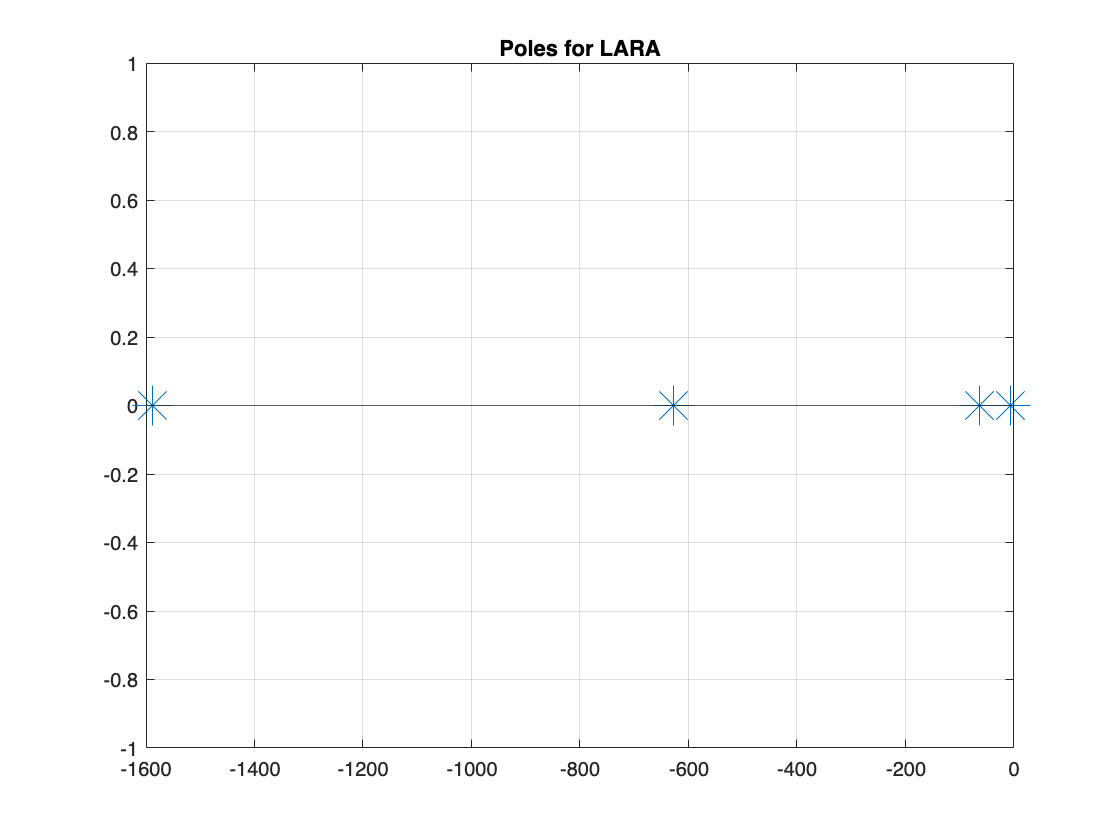


% pols plots
taus_2 = [-2*pi, -2*pi*10, -2*pi*100, tau_1_s2(1), tau_1_s2(1)];
plot(real(taus_2), imag(taus_2), '*', 'MarkerSize', 20)
grid on
xline(0);
yline(0);
title('Poles for LARA')

% Dynamic stiffness
DS1_2 = T_d/theta_l == 1/(subtheta_2(2)/T_d)

$$DS1\_2 = \frac{T_{d}}{\theta_{l}}=-\frac{K_{\mathrm{lisa}}\,K_{r}+K_{\mathrm{lsa}}\,K_{r}\,s+K_{\mathrm{lisa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{r}\,s^{4}+J_{l}\,b_{\mathrm{ra}}\,s^{4}+J_{m}\,b_{r}\,s^{4}+K_{r}\,b_{\mathrm{la}}\,s^{2}+K_{\mathrm{lsa}}\,b_{r}\,s^{2}+b_{\mathrm{la}}\,b_{r}\,s^{3}}{K_{r}\,s+J_{m}\,s^{3}+b_{r}\,s^{2}+b_{\mathrm{ra}}\,s^{2}}$$

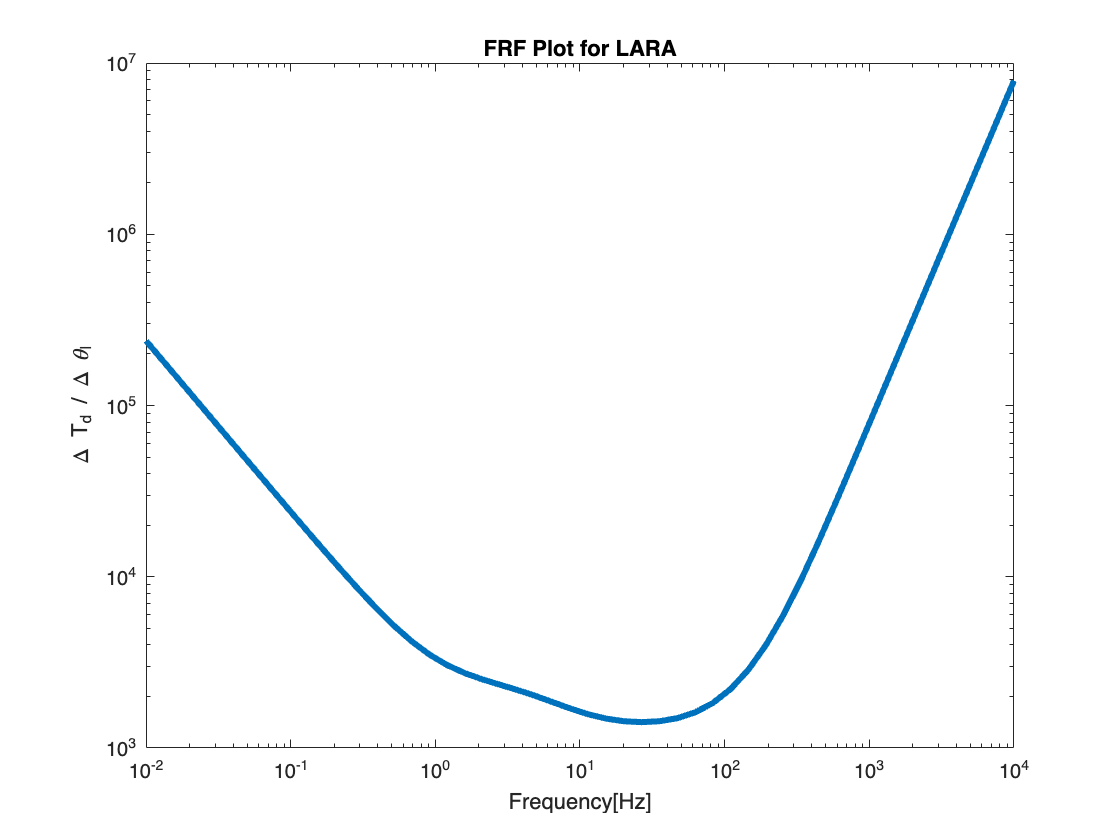

DS2_2 = subs(DS1_2);
DS3_2 = subs(DS2_2,[K_lisa,K_lsa,b_la,b_ra],[K_lisa_s2(1),K_lsa_s2(1),b_la_s2(1),b_ra_s2(1)]);

fr = logspace(-2,4);
DS4_2 = subs(DS3_2,s,2*pi*fr*1j);

loglog(fr, abs(rhs(DS4_2)), 'LineWidth', 3)
xlabel('Frequency[Hz]') 
ylabel('\Delta T_d / \Delta \theta_l') 
title('FRF Plot for LARA')

## MA

clc

syms T_em T_shaft T_d theta_l omega_l theta_m omega_m theta_l_ast omega_l_ast theta_m_ast omega_m_ast s
syms K_lisa K_lsa b_la b_ra K_misa K_msa b_ma 
syms J_m J_l b_r K_r

% Physical System Resonant Load
eq1 = theta_l == omega_l/s

$$eq1 = \theta_{l}=\frac{\omega_{l}}{s}$$

eq2 = omega_l == (1/(J_l*s)) * (T_shaft - T_d)

$$eq2 = \omega_{l}=-\frac{T_{d}-T_{\mathrm{shaft}}}{J_{l}\,s}$$

eq3 = T_shaft == (theta_m-theta_l) * K_r + (omega_m-omega_l) * b_r

$$eq3 = T_{\mathrm{shaft}}=-K_{r}\,\left(\theta_{l}-\theta_{m}\right)-b_{r}\,\left(\omega_{l}-\omega_{m}\right)$$

eq4 = theta_m == omega_m/s

$$eq4 = \theta_{m}=\frac{\omega_{m}}{s}$$

eq5 = omega_m == (1/(J_m*s)) * (T_em + (theta_l-theta_m) * K_r + (omega_l-omega_m) * b_r)

$$eq5 = \omega_{m}=\frac{T_{\mathrm{em}}+K_{r}\,\left(\theta_{l}-\theta_{m}\right)+b_{r}\,\left(\omega_{l}-\omega_{m}\right)}{J_{m}\,s}$$


J_m = 6e-3;  J_l = 2e-3;  b_r = 5e-3;  K_r = 5e+2;
syms tau_1 tau_2

% Virtual Reference for MA
eq6_3 = T_em == (theta_m_ast-theta_m) * (K_misa/s + K_msa) + (omega_m_ast - omega_m)*b_ma

$$eq6\_3 = T_{\mathrm{em}}=-\left(K_{\mathrm{msa}}+\frac{K_{\mathrm{misa}}}{s}\right)\,\left(\theta_{m}-\theta_{m^{*}}\right)-b_{\mathrm{ma}}\,\left(\omega_{m}-\omega_{m^{*}}\right)$$

eq7_3 = theta_m_ast == omega_m_ast/s

$$eq7\_3 = \theta_{m^{*}}=\frac{\omega_{m^{*}}}{s}$$


eqs_3 = [eq1,eq2,eq3,eq4,eq5,eq6_3,eq7_3];

S1_3 = solve(eqs_3, [theta_m, T_em, T_shaft, omega_m, omega_m_ast, omega_l, theta_l]);

EQ_3 = theta_m == collect(S1_3.theta_m, [theta_m_ast, T_d])

$$EQ\_3 = \begin{array}{l} \theta_{m}=\frac{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}+\sigma_{2}}{\sigma_{1}}\,\theta_{m^{*}}+\left(-\frac{b_{r}\,s^{2}+K_{r}\,s}{\sigma_{1}}\right)\,T_{d}\\ \mathrm{where}\\ \sigma_{1}=K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+\sigma_{7}+\sigma_{6}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+\sigma_{5}+J_{l}\,b_{r}\,s^{4}+J_{m}\,b_{r}\,s^{4}+\sigma_{4}+\sigma_{3}+\sigma_{2}\\ \sigma_{2}=b_{\mathrm{ma}}\,b_{r}\,s^{3}\\ \sigma_{3}=K_{\mathrm{msa}}\,b_{r}\,s^{2}\\ \sigma_{4}=K_{r}\,b_{\mathrm{ma}}\,s^{2}\\ \sigma_{5}=J_{l}\,b_{\mathrm{ma}}\,s^{4}\\ \sigma_{6}=J_{l}\,K_{\mathrm{misa}}\,s^{2}\\ \sigma_{7}=J_{l}\,K_{\mathrm{msa}}\,s^{3} \end{array}$$


subtheta_3 = children(rhs(EQ_3));
% Trasfer function for theta
TF_theta_3 = theta_m/theta_m_ast == subtheta_3(1)/theta_m_ast

$$TF\_theta\_3 = \begin{array}{l} \frac{\theta_{m}}{\theta_{m^{*}}}=\frac{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}}{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+\sigma_{6}+\sigma_{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+\sigma_{4}+J_{l}\,b_{r}\,s^{4}+J_{m}\,b_{r}\,s^{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=b_{\mathrm{ma}}\,b_{r}\,s^{3}\\ \sigma_{2}=K_{\mathrm{msa}}\,b_{r}\,s^{2}\\ \sigma_{3}=K_{r}\,b_{\mathrm{ma}}\,s^{2}\\ \sigma_{4}=J_{l}\,b_{\mathrm{ma}}\,s^{4}\\ \sigma_{5}=J_{l}\,K_{\mathrm{misa}}\,s^{2}\\ \sigma_{6}=J_{l}\,K_{\mathrm{msa}}\,s^{3} \end{array}$$


[n_theta_3, d_theta_3] = numden(rhs(TF_theta_3));
% character equation for poles
eq8_3 = collect(d_theta_3,s) == 0

$$eq8\_3 = \left(J_{l}\,J_{m}\right)\,s^{5}+\left(J_{l}\,b_{\mathrm{ma}}+J_{l}\,b_{r}+J_{m}\,b_{r}\right)\,s^{4}+\left(b_{\mathrm{ma}}\,b_{r}+J_{l}\,K_{\mathrm{msa}}+J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\left(K_{r}\,b_{\mathrm{ma}}+K_{\mathrm{msa}}\,b_{r}+J_{l}\,K_{\mathrm{misa}}\right)\,s^{2}+\left(K_{\mathrm{misa}}\,b_{r}+K_{\mathrm{msa}}\,K_{r}\right)\,s+K_{\mathrm{misa}}\,K_{r}=0$$


% fill in paramters
EQ1_3 = collect(subs(lhs(eq8_3)),s) == 0

$$EQ1\_3 = \frac{3\,s^{5}}{250000}+\left(\frac{b_{\mathrm{ma}}}{500}+\frac{1}{25000}\right)\,s^{4}+\left(\frac{K_{\mathrm{msa}}}{500}+\frac{b_{\mathrm{ma}}}{200}+4\right)\,s^{3}+\left(\frac{K_{\mathrm{msa}}}{200}+\frac{K_{\mathrm{misa}}}{500}+500\,b_{\mathrm{ma}}\right)\,s^{2}+\left(500\,K_{\mathrm{msa}}+\frac{K_{\mathrm{misa}}}{200}\right)\,s+500\,K_{\mathrm{misa}}=0$$


% poles at 1,10,100Hz
eq10_3 = (s + 2*pi) * (s + 2*pi*10) * (s + 2*pi*100) * (s + tau_1) * (s + tau_2) == 0

$$eq10\_3 = \left(s+\tau_{1}\right)\,\left(s+\tau_{2}\right)\,\left(s+2\,\pi \right)\,\left(s+20\,\pi \right)\,\left(s+200\,\pi \right)=0$$

EQ2_3 = collect(eq10_3,s)

$$EQ2\_3 = \begin{array}{l} s^{5}+\left(\tau_{1}+\tau_{2}+222\,\pi \right)\,s^{4}+\left(\tau_{1}\,\tau_{2}+\sigma_{1}+200\,\pi \,\left(\tau_{1}+\tau_{2}+22\,\pi \right)+\sigma_{3}\right)\,s^{3}+\left(\sigma_{2}+200\,\pi \,\left(\tau_{1}\,\tau_{2}+\sigma_{1}+\sigma_{3}\right)+2\,\pi \,\tau_{1}\,\tau_{2}\right)\,s^{2}+\left(200\,\pi \,\left(\sigma_{2}+2\,\pi \,\tau_{1}\,\tau_{2}\right)+40\,\tau_{1}\,\tau_{2}\,\pi^{2}\right)\,s+8000\,\tau_{1}\,\tau_{2}\,\pi^{3}=0\\ \mathrm{where}\\ \sigma_{1}=20\,\pi \,\left(\tau_{1}+\tau_{2}+2\,\pi \right)\\ \sigma_{2}=20\,\pi \,\left(\tau_{1}\,\tau_{2}+\sigma_{3}\right)\\ \sigma_{3}=2\,\pi \,\left(\tau_{1}+\tau_{2}\right) \end{array}$$


subpoles1_3 = children(lhs(EQ1_3));
subpoles2_3 = children(lhs(EQ2_3));

% solve polos
eq11_3 = (subpoles1_3{2}/s^4) / (subpoles1_3{1}/s^5) == subpoles2_3{2}/s^4

$$eq11\_3 = \frac{500\,b_{\mathrm{ma}}}{3}+\frac{10}{3}=\tau_{1}+\tau_{2}+222\,\pi$$

eq12_3 = (subpoles1_3{3}/s^3) / (subpoles1_3{1}/s^5) == subpoles2_3{3}/s^3

$$eq12\_3 = \frac{500\,K_{\mathrm{msa}}}{3}+\frac{1250\,b_{\mathrm{ma}}}{3}+\frac{1000000}{3}=\tau_{1}\,\tau_{2}+20\,\pi \,\left(\tau_{1}+\tau_{2}+2\,\pi \right)+200\,\pi \,\left(\tau_{1}+\tau_{2}+22\,\pi \right)+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)$$

eq13_3 = (subpoles1_3{4}/s^2) / (subpoles1_3{1}/s^5) == subpoles2_3{4}/s^2

$$eq13\_3 = \frac{1250\,K_{\mathrm{msa}}}{3}+\frac{500\,K_{\mathrm{misa}}}{3}+\frac{125000000\,b_{\mathrm{ma}}}{3}=20\,\pi \,\left(\tau_{1}\,\tau_{2}+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)\right)+200\,\pi \,\left(\tau_{1}\,\tau_{2}+20\,\pi \,\left(\tau_{1}+\tau_{2}+2\,\pi \right)+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)\right)+2\,\pi \,\tau_{1}\,\tau_{2}$$

eq14_3 = (subpoles1_3{5}/s) / (subpoles1_3{1}/s^5) == subpoles2_3{5}/s

$$eq14\_3 = \frac{125000000\,K_{\mathrm{msa}}}{3}+\frac{1250\,K_{\mathrm{misa}}}{3}=200\,\pi \,\left(20\,\pi \,\left(\tau_{1}\,\tau_{2}+2\,\pi \,\left(\tau_{1}+\tau_{2}\right)\right)+2\,\pi \,\tau_{1}\,\tau_{2}\right)+40\,\tau_{1}\,\tau_{2}\,\pi^{2}$$

eq15_3 = subpoles1_3{6}/ (subpoles1_3{1}/s^5) == subpoles2_3{6}

$$eq15\_3 = \frac{125000000\,K_{\mathrm{misa}}}{3}=8000\,\tau_{1}\,\tau_{2}\,\pi^{3}$$


[K_misa_s3,K_msa_s3,b_ma_s3,tau_1_s3,tau_2_s3] = solve([eq11_3,eq12_3,eq13_3,eq14_3,eq15_3],[K_misa,K_msa,b_ma,tau_1,tau_2])

$$K\_misa\_s3 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{64\,\pi^{3}\,\left(72982777500\,\pi^{2}-1387500000\,\pi -17931505\,\pi^{3}+121212333\,\pi^{4}-2664\,\pi^{5}+1920\,\pi^{6}+625000000000\right)}{101010277500\,\pi^{2}-1387500000\,\pi -24042005\,\pi^{3}+161616444\,\pi^{4}-3552\,\pi^{5}+2560\,\pi^{6}+625000000000} \end{array}$$

$$K\_msa\_s3 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{24\,\left(23125000000000\,\pi^{2}-51337500000\,\pi^{3}+2709612767500\,\pi^{4}-665315685\,\pi^{5}+4483523021\,\pi^{6}-98568\,\pi^{7}+71040\,\pi^{8}\right)}{25\,\left(101010277500\,\pi^{2}-1387500000\,\pi -24042005\,\pi^{3}+161616444\,\pi^{4}-3552\,\pi^{5}+2560\,\pi^{6}+625000000000\right)} \end{array}$$

$$b\_ma\_s3 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\left(69375000000000\,\pi -154012500000\,\pi^{2}+8406613302500\,\pi^{3}-2052002055\,\pi^{4}+13454570073\,\pi^{5}-296504\,\pi^{6}+213120\,\pi^{7}\right)}{125\,\left(101010277500\,\pi^{2}-1387500000\,\pi -24042005\,\pi^{3}+161616444\,\pi^{4}-3552\,\pi^{5}+2560\,\pi^{6}+625000000000\right)} \end{array}$$

$$tau\_1\_s3 = \begin{array}{l} \left(\begin{array}{c} \sigma_{2}-\frac{138736125000000\,\pi -\sigma_{1}+702077775000\,\pi^{2}-20178815050\,\pi^{3}+1212123330\,\pi^{4}-26640\,\pi^{5}+19200\,\pi^{6}+6250000000000}{6\,\sigma_{3}}\\ \sigma_{2}-\frac{138736125000000\,\pi +\sigma_{1}+702077775000\,\pi^{2}-20178815050\,\pi^{3}+1212123330\,\pi^{4}-26640\,\pi^{5}+19200\,\pi^{6}+6250000000000}{6\,\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,\sqrt{2505189062500000000000000000\,\pi -\frac{428571508674265625000000000000\,\pi^{2}}{3}+\frac{3406340555466118750000000000\,\pi^{3}}{9}-10065681442095673156875000000\,\pi^{4}+\frac{15951579455965337157500000\,\pi^{5}}{3}-\frac{288503675152524634211997500\,\pi^{6}}{9}+8457493463486560863000\,\pi^{7}-26627579785405580871900\,\pi^{8}+\frac{3812351047985019200\,\pi^{9}}{3}-827483638178937600\,\pi^{10}+18186126336000\,\pi^{11}-6553559040000\,\pi^{12}-\frac{4687460937500000000000000000000}{9}}\\ \sigma_{2}=\frac{10\,\left(13873612500000\,\pi +70207777500\,\pi^{2}-2017881505\,\pi^{3}+121212333\,\pi^{4}-2664\,\pi^{5}+1920\,\pi^{6}+625000000000\right)}{3\,\sigma_{3}}\\ \sigma_{3}=101010277500\,\pi^{2}-1387500000\,\pi -24042005\,\pi^{3}+161616444\,\pi^{4}-3552\,\pi^{5}+2560\,\pi^{6}+625000000000 \end{array}$$

$$tau\_2\_s3 = \begin{array}{l} \left(\begin{array}{c} \frac{138736125000000\,\pi -\sigma_{1}+702077775000\,\pi^{2}-20178815050\,\pi^{3}+1212123330\,\pi^{4}-26640\,\pi^{5}+19200\,\pi^{6}+6250000000000}{\sigma_{2}}\\ \frac{138736125000000\,\pi +\sigma_{1}+702077775000\,\pi^{2}-20178815050\,\pi^{3}+1212123330\,\pi^{4}-26640\,\pi^{5}+19200\,\pi^{6}+6250000000000}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,\sqrt{2505189062500000000000000000\,\pi -\frac{428571508674265625000000000000\,\pi^{2}}{3}+\frac{3406340555466118750000000000\,\pi^{3}}{9}-10065681442095673156875000000\,\pi^{4}+\frac{15951579455965337157500000\,\pi^{5}}{3}-\frac{288503675152524634211997500\,\pi^{6}}{9}+8457493463486560863000\,\pi^{7}-26627579785405580871900\,\pi^{8}+\frac{3812351047985019200\,\pi^{9}}{3}-827483638178937600\,\pi^{10}+18186126336000\,\pi^{11}-6553559040000\,\pi^{12}-\frac{4687460937500000000000000000000}{9}}\\ \sigma_{2}=6\,\left(101010277500\,\pi^{2}-1387500000\,\pi -24042005\,\pi^{3}+161616444\,\pi^{4}-3552\,\pi^{5}+2560\,\pi^{6}+625000000000\right) \end{array}$$

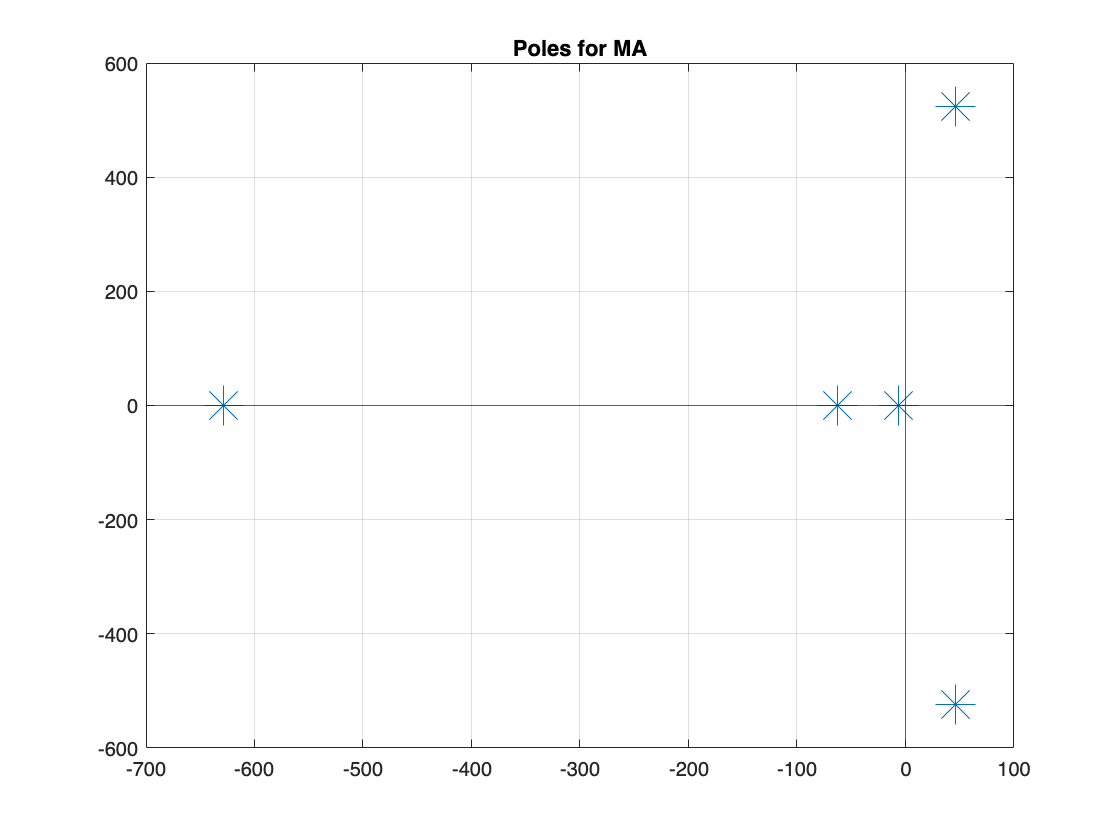


% pols plots
taus_3 = [-2*pi, -2*pi*10, -2*pi*100, tau_1_s3(1), tau_2_s3(1)];
plot(real(taus_3), imag(taus_3), '*', 'MarkerSize', 20)
grid on
xline(0);
yline(0);
title('Poles for MA')

% Dynamic stiffness
DS1_3 = T_d/theta_l == 1/(subtheta_3(2)/T_d)

$$DS1\_3 = \frac{T_{d}}{\theta_{l}}=-\frac{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{\mathrm{msa}}\,s^{3}+J_{l}\,K_{\mathrm{misa}}\,s^{2}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{\mathrm{ma}}\,s^{4}+J_{l}\,b_{r}\,s^{4}+J_{m}\,b_{r}\,s^{4}+K_{r}\,b_{\mathrm{ma}}\,s^{2}+K_{\mathrm{msa}}\,b_{r}\,s^{2}+b_{\mathrm{ma}}\,b_{r}\,s^{3}}{b_{r}\,s^{2}+K_{r}\,s}$$

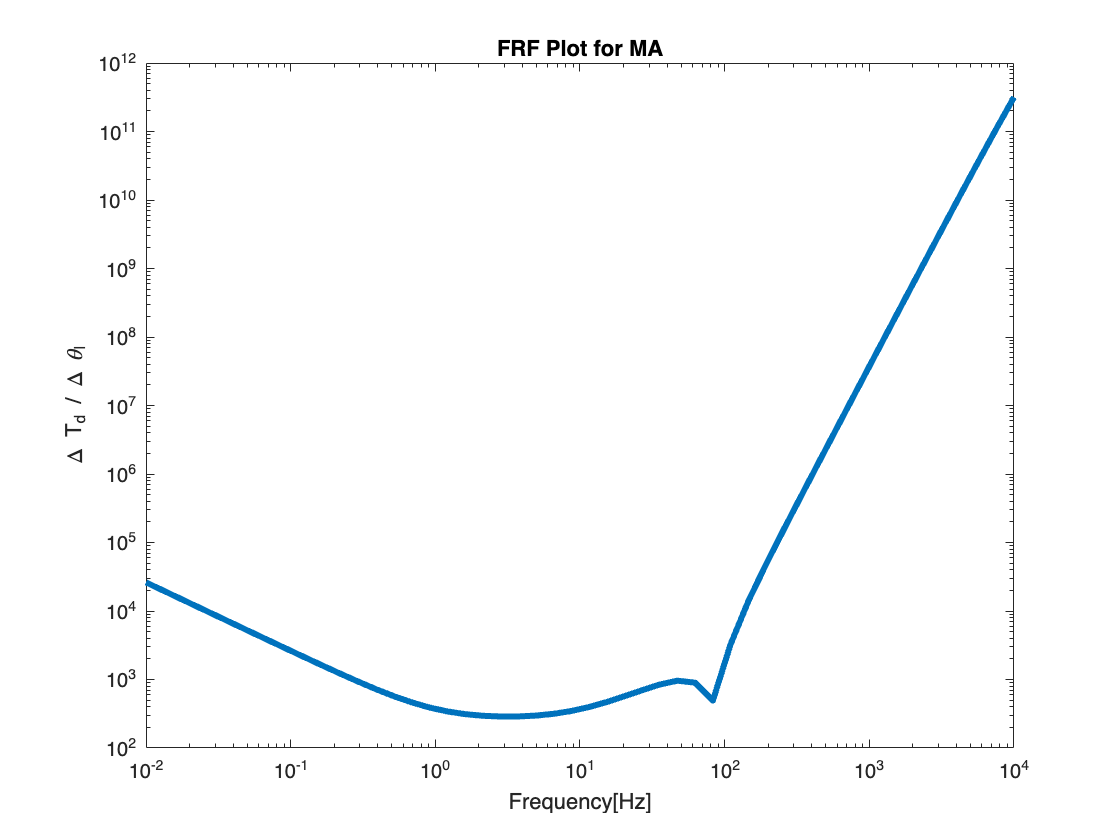

DS2_3 = subs(DS1_3);
DS3_3 = subs(DS2_3,[K_misa,K_msa,b_ma],[K_misa_s3(1),K_msa_s3(1),b_ma_s3(1)]);

fr = logspace(-2,4);
DS4_3 = subs(DS3_3,s,2*pi*fr*1j);

loglog(fr, abs(rhs(DS4_3)), 'LineWidth', 3)
xlabel('Frequency[Hz]') 
ylabel('\Delta T_d / \Delta \theta_l') 
title('FRF Plot for MA')

## MARA

% Virtual Reference for MARA
eq6_4 = T_em == (theta_m_ast-theta_m) * (K_misa/s + K_msa) + (omega_m_ast - omega_m)*b_ma + (omega_l-omega_m)*b_ra

$$eq6\_4 = T_{\mathrm{em}}=b_{\mathrm{ra}}\,\left(\omega_{l}-\omega_{m}\right)-b_{\mathrm{ma}}\,\left(\omega_{m}-\omega_{m^{*}}\right)-\left(K_{\mathrm{msa}}+\frac{K_{\mathrm{misa}}}{s}\right)\,\left(\theta_{m}-\theta_{m^{*}}\right)$$

eq7_4 = theta_m_ast == omega_m_ast/s

$$eq7\_4 = \theta_{m^{*}}=\frac{\omega_{m^{*}}}{s}$$


eqs_4 = [eq1,eq2,eq3,eq4,eq5,eq6_4,eq7_4];

S1_4 = solve(eqs_4, [theta_m, T_em, T_shaft, omega_m, omega_m_ast, omega_l, theta_l]);

EQ_4 = theta_m == collect(S1_4.theta_m, [theta_m_ast, T_d])

$$EQ\_4 = \begin{array}{l} \theta_{m}=\frac{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+\sigma_{7}+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}+\sigma_{2}}{\sigma_{1}}\,\theta_{m^{*}}+\left(-\frac{K_{r}\,s+b_{r}\,s^{2}+b_{\mathrm{ra}}\,s^{2}}{\sigma_{1}}\right)\,T_{d}\\ \mathrm{where}\\ \sigma_{1}=K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+\sigma_{7}+\sigma_{6}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+\sigma_{5}+J_{l}\,b_{r}\,s^{4}+J_{l}\,b_{\mathrm{ra}}\,s^{4}+J_{m}\,b_{r}\,s^{4}+\sigma_{4}+\sigma_{3}+\sigma_{2}\\ \sigma_{2}=b_{\mathrm{ma}}\,b_{r}\,s^{3}\\ \sigma_{3}=K_{\mathrm{msa}}\,b_{r}\,s^{2}\\ \sigma_{4}=K_{r}\,b_{\mathrm{ma}}\,s^{2}\\ \sigma_{5}=J_{l}\,b_{\mathrm{ma}}\,s^{4}\\ \sigma_{6}=J_{l}\,K_{\mathrm{misa}}\,s^{2}\\ \sigma_{7}=J_{l}\,K_{\mathrm{msa}}\,s^{3} \end{array}$$


subtheta_4 = children(rhs(EQ_4));
% Trasfer function for theta
TF_theta_4 = theta_m/theta_m_ast == subtheta_4(1)/theta_m_ast

$$TF\_theta\_4 = \begin{array}{l} \frac{\theta_{m}}{\theta_{m^{*}}}=\frac{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+\sigma_{6}+\sigma_{5}+\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}}{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+\sigma_{6}+\sigma_{5}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+\sigma_{4}+J_{l}\,b_{r}\,s^{4}+J_{l}\,b_{\mathrm{ra}}\,s^{4}+J_{m}\,b_{r}\,s^{4}+\sigma_{3}+\sigma_{2}+\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=b_{\mathrm{ma}}\,b_{r}\,s^{3}\\ \sigma_{2}=K_{\mathrm{msa}}\,b_{r}\,s^{2}\\ \sigma_{3}=K_{r}\,b_{\mathrm{ma}}\,s^{2}\\ \sigma_{4}=J_{l}\,b_{\mathrm{ma}}\,s^{4}\\ \sigma_{5}=J_{l}\,K_{\mathrm{misa}}\,s^{2}\\ \sigma_{6}=J_{l}\,K_{\mathrm{msa}}\,s^{3} \end{array}$$


[n_theta_4, d_theta_4] = numden(rhs(TF_theta_4));
% character equation for poles
eq8_4 = collect(d_theta_4,s) == 0

$$eq8\_4 = \left(J_{l}\,J_{m}\right)\,s^{5}+\left(J_{l}\,b_{\mathrm{ma}}+J_{l}\,b_{r}+J_{l}\,b_{\mathrm{ra}}+J_{m}\,b_{r}\right)\,s^{4}+\left(b_{\mathrm{ma}}\,b_{r}+J_{l}\,K_{\mathrm{msa}}+J_{l}\,K_{r}+J_{m}\,K_{r}\right)\,s^{3}+\left(K_{r}\,b_{\mathrm{ma}}+K_{\mathrm{msa}}\,b_{r}+J_{l}\,K_{\mathrm{misa}}\right)\,s^{2}+\left(K_{\mathrm{misa}}\,b_{r}+K_{\mathrm{msa}}\,K_{r}\right)\,s+K_{\mathrm{misa}}\,K_{r}=0$$


% fill in paramters
EQ1_4 = collect(subs(lhs(eq8_4)),s) == 0

$$EQ1\_4 = \frac{3\,s^{5}}{250000}+\left(\frac{b_{\mathrm{ma}}}{500}+\frac{b_{\mathrm{ra}}}{500}+\frac{1}{25000}\right)\,s^{4}+\left(\frac{K_{\mathrm{msa}}}{500}+\frac{b_{\mathrm{ma}}}{200}+4\right)\,s^{3}+\left(\frac{K_{\mathrm{msa}}}{200}+\frac{K_{\mathrm{misa}}}{500}+500\,b_{\mathrm{ma}}\right)\,s^{2}+\left(500\,K_{\mathrm{msa}}+\frac{K_{\mathrm{misa}}}{200}\right)\,s+500\,K_{\mathrm{misa}}=0$$


% poles at 1,10,100Hz
eq10_4 = (s + 2*pi) * (s + 2*pi*10) * (s + 2*pi*100) * (s + tau_1) * (s + tau_1) == 0

$$eq10\_4 = {\left(s+\tau_{1}\right)}^{2}\,\left(s+2\,\pi \right)\,\left(s+20\,\pi \right)\,\left(s+200\,\pi \right)=0$$

EQ2_4 = collect(eq10_4,s)

$$EQ2\_4 = \begin{array}{l} s^{5}+\left(2\,\tau_{1}+222\,\pi \right)\,s^{4}+\left(4\,\pi \,\tau_{1}+\sigma_{2}+200\,\pi \,\left(2\,\tau_{1}+22\,\pi \right)+{\tau_{1}}^{2}\right)\,s^{3}+\left(\sigma_{1}+\sigma_{3}+200\,\pi \,\left(4\,\pi \,\tau_{1}+\sigma_{2}+{\tau_{1}}^{2}\right)\right)\,s^{2}+\left(\pi \,\left(\sigma_{1}+\sigma_{3}\right)\,200+40\,{\tau_{1}}^{2}\,\pi^{2}\right)\,s+8000\,{\tau_{1}}^{2}\,\pi^{3}=0\\ \mathrm{where}\\ \sigma_{1}=\pi \,\left({\tau_{1}}^{2}+4\,\pi \,\tau_{1}\right)\,20\\ \sigma_{2}=20\,\pi \,\left(2\,\tau_{1}+2\,\pi \right)\\ \sigma_{3}=2\,\pi \,{\tau_{1}}^{2} \end{array}$$


subpoles1_4 = children(lhs(EQ1_4));
subpoles2_4 = children(lhs(EQ2_4));

% solve polos
eq11_4 = (subpoles1_4{2}/s^4) / (subpoles1_4{1}/s^5) == subpoles2_4{2}/s^4

$$eq11\_4 = \frac{500\,b_{\mathrm{ma}}}{3}+\frac{500\,b_{\mathrm{ra}}}{3}+\frac{10}{3}=2\,\tau_{1}+222\,\pi$$

eq12_4 = (subpoles1_4{3}/s^3) / (subpoles1_4{1}/s^5) == subpoles2_4{3}/s^3

$$eq12\_4 = \frac{500\,K_{\mathrm{msa}}}{3}+\frac{1250\,b_{\mathrm{ma}}}{3}+\frac{1000000}{3}=4\,\pi \,\tau_{1}+20\,\pi \,\left(2\,\tau_{1}+2\,\pi \right)+200\,\pi \,\left(2\,\tau_{1}+22\,\pi \right)+{\tau_{1}}^{2}$$

eq13_4 = (subpoles1_4{4}/s^2) / (subpoles1_4{1}/s^5) == subpoles2_4{4}/s^2

$$eq13\_4 = \frac{1250\,K_{\mathrm{msa}}}{3}+\frac{500\,K_{\mathrm{misa}}}{3}+\frac{125000000\,b_{\mathrm{ma}}}{3}=\pi \,\left({\tau_{1}}^{2}+4\,\pi \,\tau_{1}\right)\,20+2\,\pi \,{\tau_{1}}^{2}+200\,\pi \,\left(4\,\pi \,\tau_{1}+20\,\pi \,\left(2\,\tau_{1}+2\,\pi \right)+{\tau_{1}}^{2}\right)$$

eq14_4 = (subpoles1_4{5}/s) / (subpoles1_4{1}/s^5) == subpoles2_4{5}/s

$$eq14\_4 = \frac{125000000\,K_{\mathrm{msa}}}{3}+\frac{1250\,K_{\mathrm{misa}}}{3}=\pi \,\left(\pi \,\left({\tau_{1}}^{2}+4\,\pi \,\tau_{1}\right)\,20+2\,\pi \,{\tau_{1}}^{2}\right)\,200+40\,{\tau_{1}}^{2}\,\pi^{2}$$

eq15_4 = subpoles1_4{6}/ (subpoles1_4{1}/s^5) == subpoles2_4{6}

$$eq15\_4 = \frac{125000000\,K_{\mathrm{misa}}}{3}=8000\,{\tau_{1}}^{2}\,\pi^{3}$$


[K_misa_s4,K_msa_s4,b_ma_s4,b_ra_s4,tau_1_s4] = solve([eq11_4,eq12_4,eq13_4,eq14_4,eq15_4],[K_misa,K_msa,b_ma,b_ra,tau_1]);
K_misa_s4 = double(K_misa_s4)

K_misa_s4 = 1.0e+04 *

    2.1256
    0.0209


K_msa_s4 = double(K_msa_s4)

K_msa_s4 = 1.0e+03 *

    3.7324
    0.0391


b_ma_s4 = double(b_ma_s4)

b_ma_s4 =    55.6730
    0.9864


b_ra_s4 = double(b_ra_s4)

b_ra_s4 =   -74.1832
    5.4265


tau_1_s4 = double(tau_1_s4)

tau_1_s4 = 1.0e+03 *

   -1.8896
    0.1874


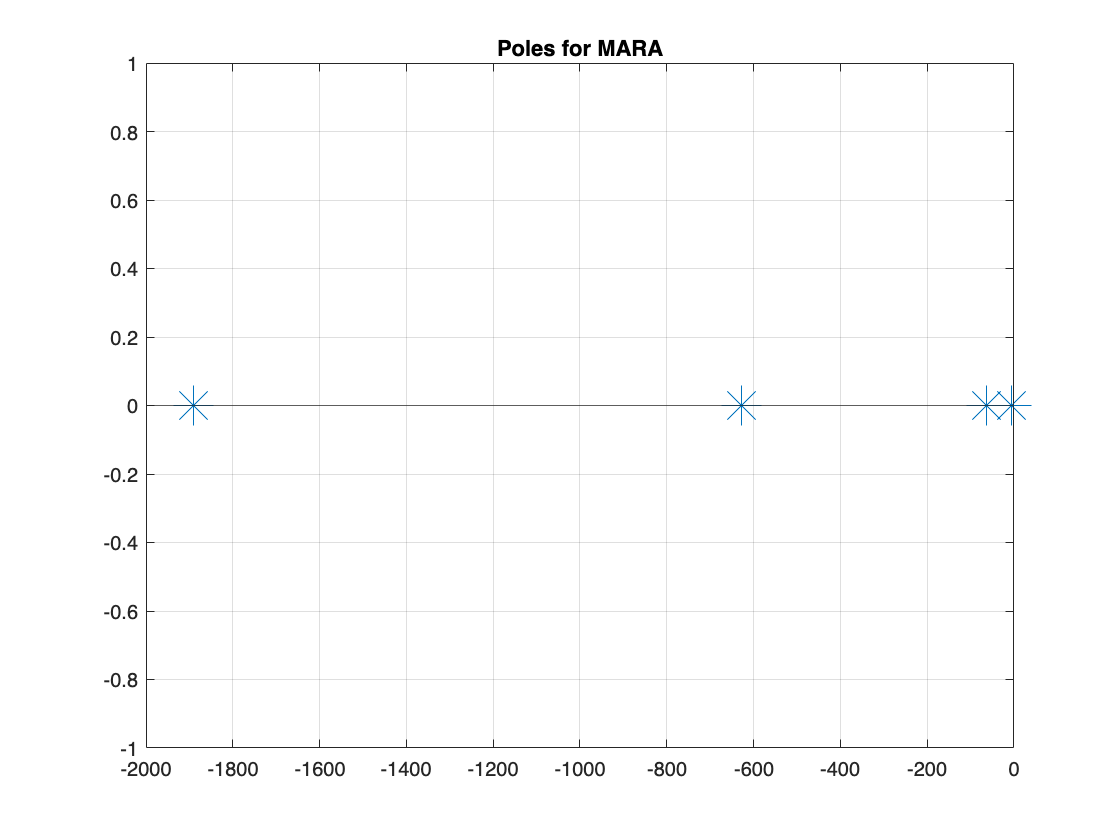


% pols plots
taus_4 = [-2*pi, -2*pi*10, -2*pi*100, tau_1_s4(1), tau_1_s4(1)];
plot(real(taus_4), imag(taus_4), '*', 'MarkerSize', 20)
grid on
xline(0);
yline(0);
title('Poles for MARA')


% Dynamic stiffness
DS1_4 = T_d/theta_l == 1/(subtheta_4(2)/T_d)

$$DS1\_4 = \frac{T_{d}}{\theta_{l}}=-\frac{K_{\mathrm{misa}}\,K_{r}+K_{\mathrm{msa}}\,K_{r}\,s+K_{\mathrm{misa}}\,b_{r}\,s+J_{l}\,J_{m}\,s^{5}+J_{l}\,K_{\mathrm{msa}}\,s^{3}+J_{l}\,K_{\mathrm{misa}}\,s^{2}+J_{l}\,K_{r}\,s^{3}+J_{m}\,K_{r}\,s^{3}+J_{l}\,b_{\mathrm{ma}}\,s^{4}+J_{l}\,b_{r}\,s^{4}+J_{l}\,b_{\mathrm{ra}}\,s^{4}+J_{m}\,b_{r}\,s^{4}+K_{r}\,b_{\mathrm{ma}}\,s^{2}+K_{\mathrm{msa}}\,b_{r}\,s^{2}+b_{\mathrm{ma}}\,b_{r}\,s^{3}}{K_{r}\,s+b_{r}\,s^{2}+b_{\mathrm{ra}}\,s^{2}}$$

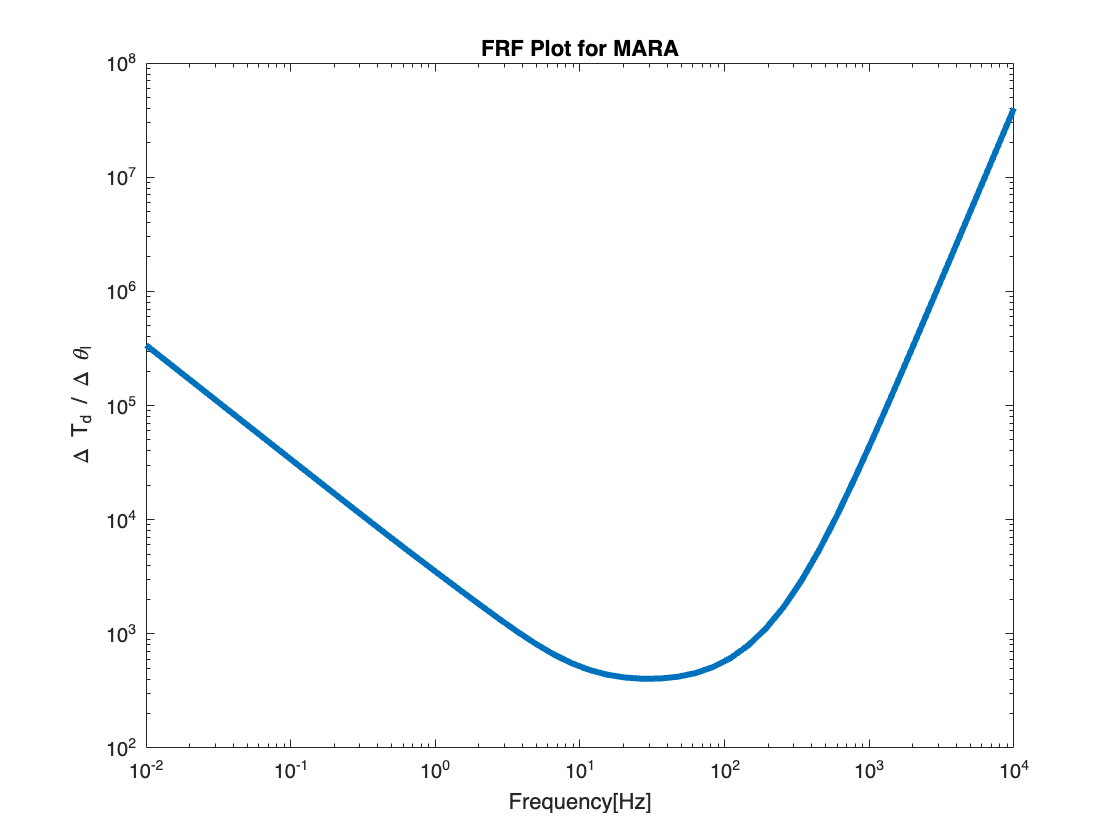

DS2_4 = subs(DS1_4);
DS3_4 = subs(DS2_4,[K_misa,K_msa,b_ma,b_ra],[K_misa_s4(1),K_msa_s4(1),b_ma_s4(1),b_ra_s4(1)]);

fr = logspace(-2,4);
DS4_4 = subs(DS3_4,s,2*pi*fr*1j);

loglog(fr, abs(rhs(DS4_4)), 'LineWidth', 3)
xlabel('Frequency[Hz]') 
ylabel('\Delta T_d / \Delta \theta_l') 
title('FRF Plot for MARA')

## Conclusion

Campare with these four result, the MARA and LARA is more smooth than MA and LA because it decouped the dumping.

Also, Campare with the MA and LA, the dumping has a more serious impact on the load than on the motor.